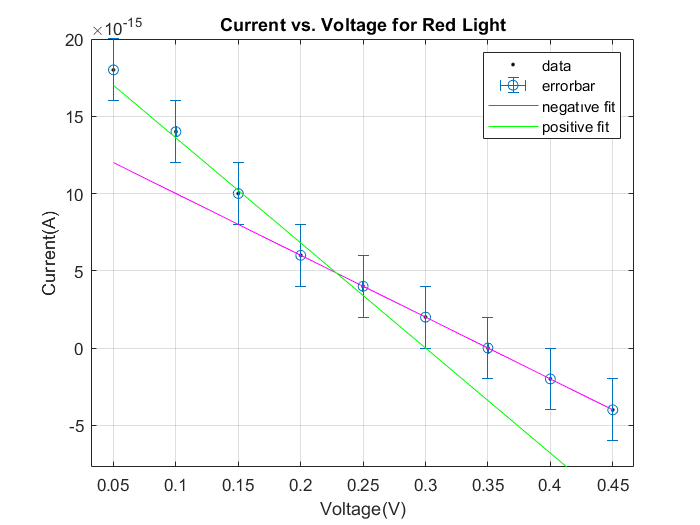

plot(REDvoltage,REDcurrent,'.k')
hold on
grid on
%%CREATING ERROBARS
xpos=0.0001.*[1 1 1 1 1 1 1 1 1];
xneg=xpos;
yneg=(0.2e-14).*[1 1 1 1 1 1 1 1 1];
ypos=yneg;
errorbar(REDvoltage,REDcurrent,yneg,ypos,xneg,xpos,'o');

%%NEGATIVE SIDE FIT
%Linear model Poly1:
 %    f(x) = p1*x + p2
%Coefficients:
 %      p1 =      -4e-14
  %     p2 =     1.4e-14

%Goodness of fit:
 % SSE: 3.796e-59
 % R-square: 1
 % Adjusted R-square: NaN
 % RMSE: NaN
 p1 =      -4e-14;
 p2 =     1.4e-14;
f=p1.*REDvoltage+p2;

plot(REDvoltage,f,'m')

%%POSITIVE SIDE FIT
%Linear model Poly1:
 %    g = p3*x + p4
%Coefficients (with 95% confidence bounds):
 %      p3 =    -6.800e-14 \mp 1.490e-14 
  %     p4 =    (2.040e-14  \mp 0.274e-14)

%Goodness of fit:
 % SSE: 1.2e-30
 % R-square: 0.9797
 % Adjusted R-square: 0.9695
 % RMSE: 7.746e-16
 p3 =    -6.8e-14;
 p4 =    2.04e-14;
 g=p3.*REDvoltage+p4;
 
 plot(REDvoltage,g,'g')

xlim([0.032 0.467])
ylim([-0.0000000000000077 0.0000000000000200])
legend({'data','errorbar','negatıve fit','positive fit'})
title('Current vs. Voltage for Red Light')
xlabel('Voltage(V)')
ylabel('Current(A)')

 %%LABELING